## ECE 537 : Assignment 1

Group 9 - Ashlynn Steeves, Derrell D'Souza

close all;
clear all;
clc;

**Task 1**:  Develop a matlab function that creates K samples of D-dimensional Gaussian data with arbitrary specified mean µ and covariance matrix Σ

Solution:

Please refer to the function **gaussian_data_1() **

**Task 2**:  Fully test your developed function to ensure that it indeed produces D-dimensional Gaussian data with the correct mean vector and covariance matrix.

Solution:

% test 1
mu1= [0 0 0]

mu1 =      0     0     0


sigma1 = eye(3,3)

sigma1 =      1     0     0
     0     1     0
     0     0     1


D1 = gaussian_data_1(1000,3,mu1,sigma1)

D1 =     0.3874    0.3171    0.2491
   -1.2884   -0.3469    0.3246
    1.3851   -1.0254   -0.7170
   -0.2508   -1.0602    1.0010
   -0.6152    0.0407    0.6374
   -0.0800   -0.0376    0.5787
   -0.5119   -1.6875    1.1948
    0.2513   -0.1598    0.0837
    1.3413   -1.5795   -1.2121
    1.1484    1.0016   -0.0779


mu1_s = mean(D1)

mu1_s =     0.0127    0.0038   -0.0432


sigma1_s = cov(D1)

sigma1_s =     0.9465    0.0100   -0.0112
    0.0100    0.9702   -0.0230
   -0.0112   -0.0230    0.8788



% test 2
mu2 = 5

mu2 = 5

sigma2 = 7

sigma2 = 7

D2 = gaussian_data_1(1000,1,mu2,sigma2)

D2 =     4.3302
    7.6958
    6.1997
    3.3597
    6.1106
    5.0045
    3.9389
    2.8407
    3.9278
    6.0997


mu2_s = mean(D2)

mu2_s = 5.0758

sigma2_s = cov(D2)

sigma2_s = 6.4899


% test 3
mu3 =  [-2 -5 -5]

mu3 =     -2    -5    -5


sigma3 = [6.8928 -1.3750 3.1945 ;-1.3750 3.3572 0.6945;3.1945 0.6945 3.7500]

sigma3 =     6.8928   -1.3750    3.1945
   -1.3750    3.3572    0.6945
    3.1945    0.6945    3.7500


D3 = gaussian_data_1(1000,3,mu3,sigma3)

D3 =     0.4889   -4.6357   -4.4036
   -0.2338   -6.7956   -6.0966
   -1.3127   -7.9517   -4.7361
    1.0763   -6.2926   -5.2037
    3.6873   -3.7647   -1.5553
    1.2989   -3.7662   -2.2066
    0.3101   -5.2378   -3.9439
   -1.0517   -4.4878   -3.4268
   -6.0440   -2.8367   -5.6246
   -2.5400   -5.1389   -5.2754


mu3_s = mean(D3)

mu3_s =    -1.8249   -5.1160   -5.0229


sigma3_s = cov(D3)

sigma3_s =     6.3235   -1.2503    2.9475
   -1.2503    3.3391    0.7740
    2.9475    0.7740    3.8182


**Comments:**

The mean and the covariance of the data obtained from the function gaussian_data_1() are not exactly as specified in the function arguments.

**Task 3**:  Discuss why, when K < ∞, the Matlab’s computed covariance matrix for your Gaussian generated data will not exactly match the covariance you prescribed.

Solution:

K < ∞ implies that we generate finite samples from a given distribution. The covariance matrix for gaussian generated data is the sample covariance and therefore will not exactly match the covariance we prescribe.

**Task 4**:  Develop an appropriate methadology to correct this.

Solution: 

To correct for this and obtain a sample covariance matrix equal to the population covariance matrix, we need to generate a random normal distribution with zero-mean and identity-covariance. As explained in Task 3, due to finite samples, the mean will not be exactly zero and covariance will not exactly be an identity matrix. Therefore, we need to perform transformations to the data to establish a true zero mean and identity covariance matrix. The former can be achieved by subtracting the sample mean (which is not exactly zero) from all the datapoints and the latter can be achieved by performing a whitening transform on the zero mean gaussian distribution. To obtain the distribution with a specified mean $$\mu$$ and covariance $\Sigma$, we first apply the inverse whitening transform (also known as coloring transform) to the zero-mean identity-covariance gaussian distribution to obtain gaussian distribution with zero-mean and covariance $\Sigma$ and then add the mean $$\mu$$ to this data to produce a gaussian distribution with an exact mean $$\mu$$ and covariance $\Sigma$.

The function **gaussian_data()** performs the methadology explained above

**Task 5**: Use your created function to create 1000 data samples each drawn from the three 3-dimensional Gaussian data classes A, B, and C.

Solution:

K = 1000;
D = 3;

% Dataset A
mu_A = [0 4 7];
sigma_A = [6.5000 2.1651 1.2500 ; 2.1651 5.1250 2.3816;1.2500 2.3816 2.3750];
data_A = gaussian_data(K,D,mu_A,sigma_A);
mu_As = mean(data_A) % sample mean from generated dataset A

mu_As =    -0.0000    4.0000    7.0000


sigma_As = cov(data_A) % sample covarriance from generated dataset A

sigma_As =     6.5000    2.1651    1.2500
    2.1651    5.1250    2.3816
    1.2500    2.3816    2.3750



% Dataset B
mu_B = [10 5 5];
sigma_B = [3.0184 0.4331 -1.4481; 0.4331 0.9436 -0.6456 ;-1.4481 -0.6456 1.2880];
data_B = gaussian_data(K,D,mu_B,sigma_B);
mu_Bs = mean(data_B) % sample mean from generated dataset B

mu_Bs =    10.0000    5.0000    5.0000


sigma_Bs = cov(data_B) % sample covarriance from generated dataset B

sigma_Bs =     3.0184    0.4331   -1.4481
    0.4331    0.9436   -0.6456
   -1.4481   -0.6456    1.2880



% Dataset C
mu_C = [-2 -5 -5];
sigma_C = [6.8928 -1.3750 3.1945 ;-1.3750 3.3572 0.6945;3.1945 0.6945 3.7500];
data_C = gaussian_data(K,D,mu_C,sigma_C);
mu_Cs = mean(data_C) % sample mean from generated dataset C

mu_Cs =    -2.0000   -5.0000   -5.0000


sigma_Cs = cov(data_C) % sample covarriance from generated dataset B

sigma_Cs =     6.8928   -1.3750    3.1945
   -1.3750    3.3572    0.6945
    3.1945    0.6945    3.7500


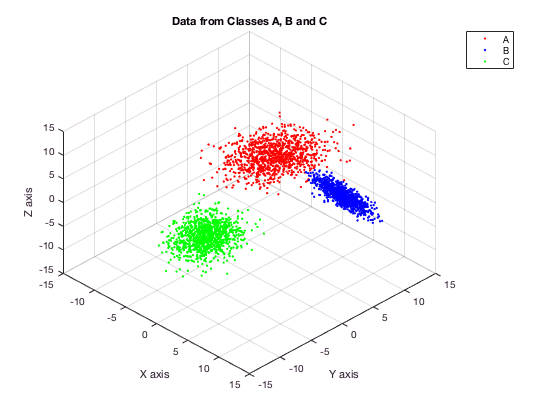


figure()
plot3(data_A(:,1),data_A(:,2),data_A(:,3),'color','r','Marker','.','LineStyle','none')
hold on
plot3(data_B(:,1),data_B(:,2),data_B(:,3),'color','b','Marker','.','LineStyle','none')
plot3(data_C(:,1),data_C(:,2),data_C(:,3),'color','g','Marker','.','LineStyle','none')
xlabel('X axis'); ylabel('Y axis'); zlabel('Z axis');
xlim([-15 15]);
ylim([-15 15]);
zlim([-15 15]);
view([45 45]);
title('Data from Classes A, B and C')
legend('A','B','C')
grid on
hold off;

**Task 6**: Use matlab’s ellipsoid() function to create contour intervals for Classes A, B, and C at one, two, and three standard deviations from µA, µB, and µC and also on the same plot the principal axes of each generated Gaussian contour ellipses using matlab’s line() function. 

Solution:

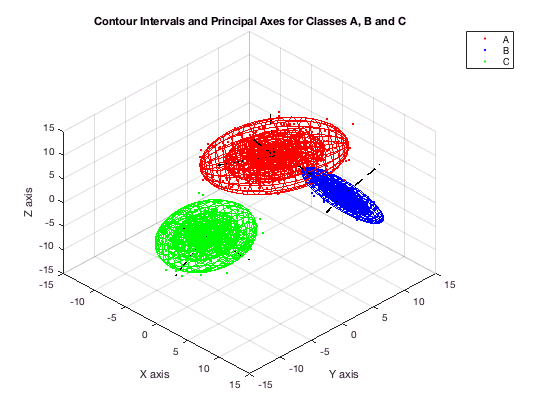

figure()
axes_plot = axes;
hold(axes_plot,'on');
A = plot3(data_A(:,1),data_A(:,2),data_A(:,3),'color','r','Marker','.','LineStyle','none');
B = plot3(data_B(:,1),data_B(:,2),data_B(:,3),'color','b','Marker','.','LineStyle','none');
C = plot3(data_C(:,1),data_C(:,2),data_C(:,3),'color','g','Marker','.','LineStyle','none');

% Class A
[vA,dA] = eig(sigma_A);

% Contour intervals
[xA1,yA1,zA1,xA2,yA2,zA2,xA3,yA3,zA3] = ellipse_cord(data_A);
A1 = surf(xA1, yA1, zA1,'EdgeColor', 'r','FaceAlpha',0);
A2 = surf(xA2, yA2, zA2, 'EdgeColor', 'r','FaceAlpha',0);
A3 = surf(xA3, yA3, zA3,'EdgeColor', 'r','FaceAlpha',0);

% Principal axes
line([mu_A(1) 7*vA(1,1)+mu_A(1)],[mu_A(2) 7*vA(2,1)+mu_A(2)], [mu_A(3) 7*vA(3,1)+ mu_A(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
line([mu_A(1) 7*vA(1,2)+mu_A(1)],[mu_A(2) 7*vA(2,2)+mu_A(2)], [mu_A(3) 7*vA(3,2)+mu_A(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
line([mu_A(1) 7*vA(1,3)+mu_A(1)],[mu_A(2) 7*vA(2,3)+mu_A(2)], [mu_A(3) 7*vA(3,3)+ mu_A(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')

% Class B
[vB,dB] = eig(sigma_B);

% Contour intervals
[xB1,yB1,zB1,xB2,yB2,zB2,xB3,yB3,zB3] = ellipse_cord(data_B);
B1 = surf(xB1, yB1, zB1,'EdgeColor', 'b','FaceAlpha',0);
B2 = surf(xB2, yB2, zB2, 'EdgeColor', 'b','FaceAlpha',0);
B3 = surf(xB3, yB3, zB3,'EdgeColor', 'b','FaceAlpha',0);

% Principal axes
line([mu_B(1); 7*vB(1,1)+ mu_B(1)],[mu_B(2); 7*vB(2,1)+ mu_B(2)], [mu_B(3); 7*vB(3,1)+ mu_B(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
line([mu_B(1) 7*vB(1,2)+ mu_B(1)],[mu_B(2) 7*vB(2,2)+ mu_B(2)], [mu_B(3) 7*vB(3,2)+ mu_B(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
line([mu_B(1) 7*vB(1,3)+ mu_B(1)],[mu_B(2) 7*vB(2,3)+ mu_B(2)], [mu_B(3) 7*vB(3,3)+ mu_B(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')

% Class C
[vC,dC] = eig(sigma_C);

% Contour intervals
[xC1,yC1,zC1,xC2,yC2,zC2,xC3,yC3,zC3] = ellipse_cord(data_C);
C1 = surf(xC1, yC1, zC1,'EdgeColor', 'g','FaceAlpha',0);
C2 = surf(xC2, yC2, zC2, 'EdgeColor', 'g','FaceAlpha',0);
C3 = surf(xC3, yC3, zC3,'EdgeColor', 'g','FaceAlpha',0);

% Principal axes
line([mu_C(1) 7*vC(1,1)+mu_C(1)],[mu_C(2) 7*vC(2,1)+mu_C(2)], [mu_C(3) 7*vC(3,1)+mu_C(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
line([mu_C(1) 7*vC(1,2)+mu_C(1)],[mu_C(2) 7*vC(2,2)+mu_C(2)], [mu_C(3) 7*vC(3,2)+mu_C(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')
line([mu_C(1) 7*vC(1,3)+mu_C(1)],[mu_C(2) 7*vC(2,3)+mu_C(2)], [mu_C(3) 5*vC(3,3)+mu_C(3)],'color', 'k','LineWidth',1.5,'LineStyle','--')

xlabel('X axis'); ylabel('Y axis'); zlabel('Z axis');
xlim([-15 15]);
ylim([-15 15]);
zlim([-15 15]);
view([45 45]);
title('Contour Intervals and Principal Axes for Classes A, B and C')
legend([A,B,C],'A','B','C')
grid(axes_plot,'on');
hold(axes_plot,'off');

function D = gaussian_data_1(K,D,mu,sigma)
    x = randn(K,D); % zero mean and identity covariance;
    
    %Arbitrary specified user covariance needs to be converted in a matrix
    %with specific properties.
    [R,p]=chol(sigma); 
    if p>0
        x=x*sqrtm(sigma);
    else
        x=x*R;
    end

    D = x + mu; %data with arbitrary specified mean mu and covariance matrix sigma 
    
end 

function f = gaussian_data(K,D,mu,sigma)
    % generate a subset of samples from normal distribution
    N = randn(K,D);
    % centralize the data at zero-mean
    N_c = N - mean(N);
    % obtain eigen values and eigen vectors for covariance of N
    [v,d] = eig(cov(N_c));
    % generate the whitening transform
    R = v*inv(sqrt(d));
    %apply the whitening transform on the centralized data
    W  = N_c*R;
    %obtain eigen values and eigen vectors for given covariance
    [vn,dn] = eig(sigma);
    % generate the inverse whitening transform
    R_inv = sqrt(dn)*inv(vn);
    % apply the inverse whitening transfrom on the whitened gaussian data
    f = W*R_inv;  
    % centralize the data at mu
    f = f + mu;
end 

function [x1,y1,z1,x2,y2,z2,x3,y3,z3] = ellipse_cord(data)

    mu = mean(data);
    sigma = cov(data);
    [v,d] = eig(sigma);
    %plot ellipsoid for three standard deviations and zero mean
    radius = sqrt(diag(d));
    [x1,y1,z1] = ellipsoid(0, 0, 0, radius(1),radius(2),radius(3));
    [x2,y2,z2] = ellipsoid(0, 0, 0, 2*radius(1),2*radius(2),2*radius(3));
    [x3,y3,z3] = ellipsoid(0, 0, 0, 3*radius(1),3*radius(2),3*radius(3));
    
    %rotate ellipsoids
    x1 = kron(v(:,1),x1);y1 = kron(v(:,2),y1);z1 = kron(v(:,3),z1);
    x2 = kron(v(:,1),x2);y2 = kron(v(:,2),y2);z2 = kron(v(:,3),z2);
    x3 = kron(v(:,1),x3);y3 = kron(v(:,2),y3);z3 = kron(v(:,3),z3);
    dat1 = x1 + y1 + z1; dat2 = x2 + y2 + z2 ; dat3 = x3 + y3 + z3; % to account for rotation of all three axis 
    n = size(dat1,2);
    
    %shift the ellipsoids
    x1 = dat1(1:n,:) + mu(1); y1 = dat1(n+1:2*n,:) + mu(2); z1 = dat1(2*n+1:end,:) + mu(3); 
    x2 = dat2(1:n,:) + mu(1); y2 = dat2(n+1:2*n,:) + mu(2); z2 = dat2(2*n+1:end,:) + mu(3);
    x3 = dat3(1:n,:) + mu(1); y3 = dat3(n+1:2*n,:) + mu(2); z3 = dat3(2*n+1:end,:) + mu(3);
       
end 











